# 09 | Power-MWT mixed-effects association

INPUT: power and MWT tables with matching RatID/Day keys. OUTPUT: six slopes, 95% CIs, raw p values and six-band BH-FDR adjusted p values. TOOLBOX: Statistics and Machine Learning. DEFAULT DATA ARE SYNTHETIC: 21 rows from eight fictitious rats, shaped like the study design. They are not the manuscript observations or results.

## 1. Paths and column definitions

codeDir = 'H:\closed-loop data paper\0 group analysis\GATE-Pain\code\offline data analysis_v2_20260923';
addpath(fullfile(codeDir,'functions'));
outDir=gate_output_dir(codeDir,'09_association');
powerFile=fullfile(codeDir,'example_inputs','synthetic_rat_day_power.csv');
mwtFile=fullfile(codeDir,'example_inputs','synthetic_rat_day_mwt.csv');
bands={'delta','theta','alpha','lowbeta','highbeta','gamma'};
keys={'RatID','Day'};

## 2. Read tables and verify animal/day identities

P=readtable(powerFile,'TextType','string','Delimiter',',','VariableNamingRule','preserve');
B=readtable(mwtFile,'TextType','string','Delimiter',',','VariableNamingRule','preserve');
assert(all(ismember([keys bands],P.Properties.VariableNames)),'Missing power columns.');
assert(all(ismember([keys {'MWT_g'}],B.Properties.VariableNames)),'Missing MWT columns.');
assert(~any(ismissing(P.RatID)) && ~any(ismissing(B.RatID)));
assert(height(unique(P(:,keys),'rows'))==height(P),'Duplicate power rat/day keys.');
assert(height(unique(B(:,keys),'rows'))==height(B),'Duplicate MWT rat/day keys.');
assert(height(P)==height(B) && all(ismember(P(:,keys),B(:,keys),'rows')), ...
    'Power and behavior keys do not match; do not pair rows by position.');
T=innerjoin(P,B,'Keys',keys);
T=sortrows(T,keys); T.RatID=categorical(T.RatID);
assert(all(isfinite(T.Day)) && all(isfinite(T.MWT_g)));
fprintf('Matched %d rat/day observations from %d rats.\n',height(T),numel(categories(T.RatID)));

Matched 21 rat/day observations from 8 rats.


writetable(T,fullfile(outDir,'SYNTHETIC_matched_inputs.csv'));

## 3. Fit one repeated-measures model per band

Power is a fixed predictor and rat identity has a random intercept. Day is an exact matching key here, not a fixed covariate in this example. REML and residual degrees of freedom follow the supplied association script. The CI and p value must come from the SAME coefficient/model.

beta=NaN(6,1); ciLow=beta; ciHigh=beta; rawP=beta; standardized=beta;
models=cell(6,1);
for b=1:numel(bands)
    Q=table(T.RatID,T.(bands{b}),T.MWT_g,'VariableNames',{'RatID','Power','MWT'});
    assert(all(isfinite(Q.Power)) && std(Q.Power)>0 && std(Q.MWT)>0);
    model=fitlme(Q,'MWT ~ Power + (1|RatID)','FitMethod','REML');
    coefficient=find(strcmp(model.CoefficientNames,'Power'));
    CI=coefCI(model);             % Default two-sided 95% coefficient interval.
    beta(b)=model.Coefficients.Estimate(coefficient);
    ciLow(b)=CI(coefficient,1); ciHigh(b)=CI(coefficient,2);
    rawP(b)=model.Coefficients.pValue(coefficient);
    standardized(b)=beta(b)*std(Q.Power)/std(Q.MWT);
    models{b}=model;
end

## 4. Correct the six-band test family

Perform one adjustment across these six associations, without selecting only nominally significant bands first. BH changes p values, not slopes or CIs.

adjustedP=gate_bh_fdr(rawP);
R=table(string(bands(:)),beta,ciLow,ciHigh,standardized,rawP,adjustedP, ...
    'VariableNames',{'Band','Slope_g_per_dB','CI95_low','CI95_high', ...
    'StandardizedSlope','RawP','BH_FDR_P'});
writetable(R,fullfile(outDir,'SYNTHETIC_association_results.csv'));
save(fullfile(outDir,'SYNTHETIC_association_models.mat'),'models','T','R');
disp(R);

       Band       Slope_g_per_dB    CI95_low    CI95_high    StandardizedSlope      RawP      BH_FDR_P
    __________    ______________    ________    _________    _________________    ________    ________

    "delta"          -0.33898       -6.0567       5.3788         -0.027865         0.90255    0.90255 
    "theta"           -0.8574       -5.5714       3.8566          -0.08453         0.70766    0.84919 
    "alpha"           -2.6272       -8.3877       3.1334          -0.20965          0.3518    0.61548 
    "lowbeta"          2.3225       -2.9894       7.6344           0.19831          0.3716    0.61548 
    "highbeta"        -1.8637       -6.4971       2.7696          -0.19353         0.41032    0.61548 
    "gamma"            -4.898       -10.735      0.93925          -0.38572        0.095153    0.57092 



## 5. Display coefficient uncertainty and matched observations 

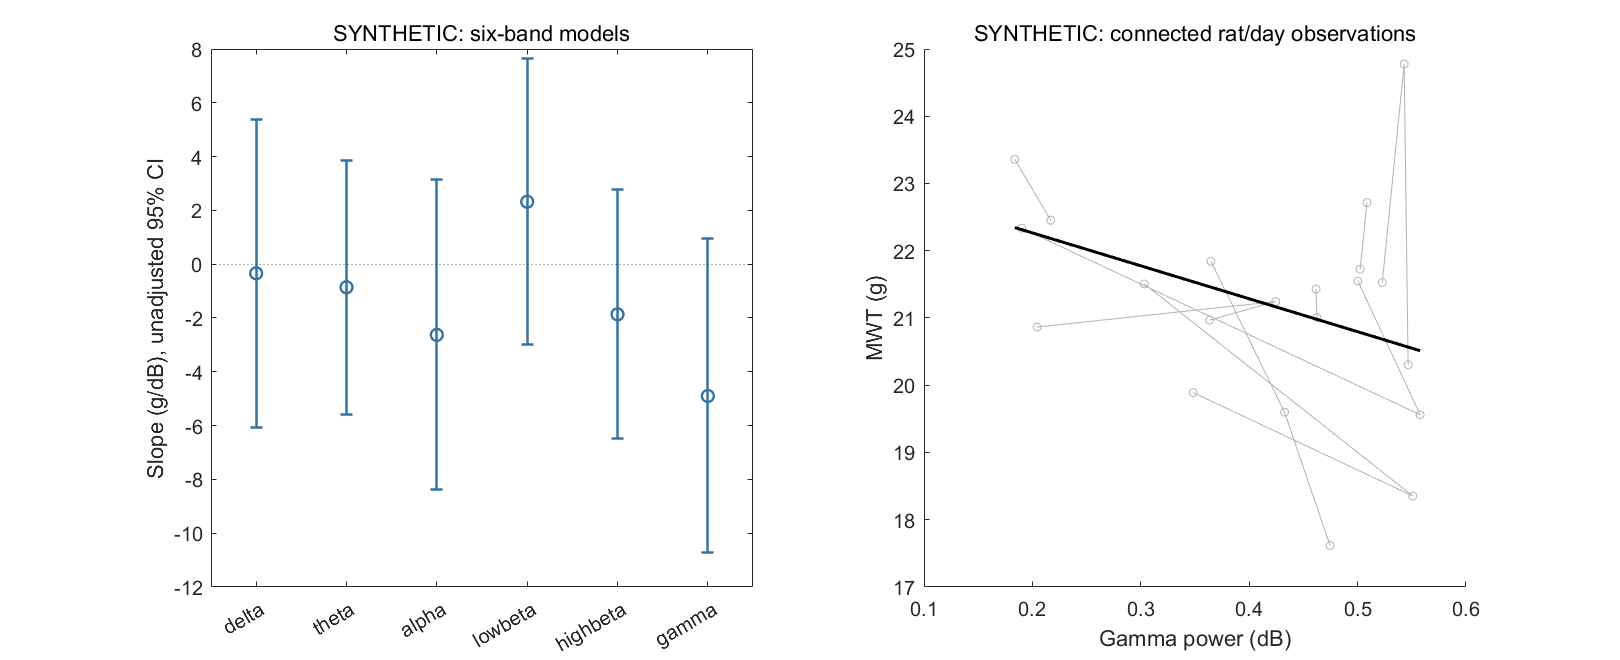

fig=figure('Color','w','Position',[100 100 1080 440]);
subplot(1,2,1);
errorbar(1:6,beta,beta-ciLow,ciHigh-beta,'o','Color',[0.2 0.45 0.65],'LineWidth',1.2);
yline(0,':'); xlim([0.5 6.5]);
set(gca,'XTick',1:6,'XTickLabel',bands); xtickangle(30);
ylabel('Slope (g/dB), unadjusted 95% CI'); title('SYNTHETIC: six-band models');
subplot(1,2,2); hold on;
ratNames=categories(T.RatID);
for r=1:numel(ratNames)
    mask=T.RatID==ratNames{r};
    plot(T.gamma(mask),T.MWT_g(mask),'-o','Color',[0.7 0.7 0.7],'MarkerSize',4);
end
gammaModel=models{6}; xGrid=linspace(min(T.gamma),max(T.gamma),50)';
predictionInput=table(repmat(T.RatID(1),numel(xGrid),1),xGrid,'VariableNames',{'RatID','Power'});
prediction=predict(gammaModel,predictionInput,'Conditional',false);
plot(xGrid,prediction,'k-','LineWidth',1.5);
xlabel('Gamma power (dB)'); ylabel('MWT (g)'); title('SYNTHETIC: connected rat/day observations');
exportgraphics(fig,fullfile(outDir,'SYNTHETIC_association.png'),'Resolution',180);

disp('Demonstration only: do not quote these synthetic estimates as study results.');

Demonstration only: do not quote these synthetic estimates as study results.
